% Show that series
% u(x,n)=1/2^(n-1)*((2*x+1)/(x+2))^n
% uniformly converges in the interval [-1;1]

syms x n;
u(x,n)=1/2^(n-1)*((2*x+1)/(x+2))^n

$$u(x, n) = 2^{1-n}\,{\left(\frac{2\,x+1}{x+2}\right)}^{n}$$

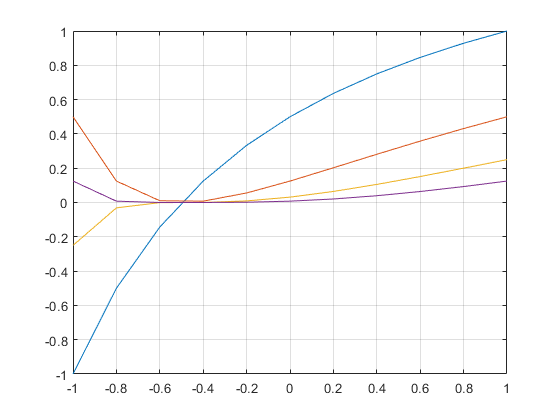


syms i;
x1=-1:0.2:1;
for i=1:4
    y1=u(x1,i);
    plot(x1,y1)
    hold on
    grid on
end
hold off


x=-1

x = -1

u1(n)=u(x,n)

$$u1(n) = {\left(-1\right)}^{n}\,2^{1-n}$$

% (-1)^n*2^(1 - n)
S=symsum(u(x,n),n,1,inf)

$$S = -\frac{2}{3}$$

% -2/3

x=0

x = 0

u1(n)=u(x,n)

$$u1(n) = {\left(\frac{1}{2}\right)}^{n}\,2^{1-n}$$

% (1/2)^n*2^(1 - n)
S=symsum(u(x,n),n,1,inf)

$$S = \frac{2}{3}$$

% 2/3

x=1

x = 1

u1(n)=u(x,n)

$$u1(n) = 2^{1-n}$$

% 2^(1 - n)
S=symsum(u(x,n),n,1,inf)

$$S = 2$$

% 2

clear
syms x n;
u(x,n)=1/2^(n-1)*((2*x+1)/(x+2))^n

$$u(x, n) = 2^{1-n}\,{\left(\frac{2\,x+1}{x+2}\right)}^{n}$$


d(x,n)=simplify(u(x,n+1)/u(x,n))

$$d(x, n) = \frac{2\,x+1}{2\,\left(x+2\right)}$$

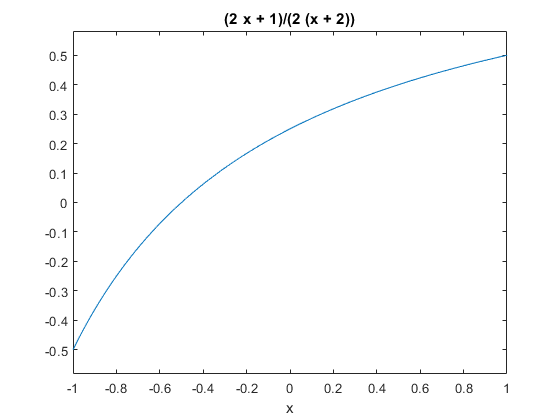

% (2*x + 1)/(2*(x + 2))
ezplot(d(x,n),[-1,1])


% In range -1<x<1 => |d(x,n)| < 1/2 < 1 => series converges
